clear
close all

hr=0;   minu='00';   expri='largens';  lev=12; 

%---DA or forecast time---
infilenam='wrfmean';    type='mean';
%infilenam='output/fcstmean';  type=infilenam(8:11);  

%---experimental setting---
dom='02'; year='2008'; mon='06'; date='16';    % time setting
indir=['./',expri]; 
outdir='./';   % path of the figure output
%---set
addpath('./m_map1.4/')
addpath('./colorbar/');
load './colormap_vr.mat';  cmap=colormap_vr;
L=[-8 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 8];
%------
varinam='Vr';    filenam=[expri,'_vr-model_']; 
plon=[118.9 121.8];   plat=[21 24.3];
g=9.81;  R=6.37122e6;
%
xrad=120.0860; yrad=23.1467; zrad=38;
xradd=120.0860*pi/180; yradd=23.1467*pi/180;

   ti=hr

ti = 0

%---set filename---
   s_hr=num2str(ti,'%2.2d');  % start time string
   infile=[indir,'/',infilenam,'_d',dom,'_',year,'-',mon,'-',date,'_',s_hr,'%3A',minu,'%3A00'];
%------read netcdf data--------
   ncid = netcdf.open(infile,'NC_NOWRITE');
      varid  =netcdf.inqDimID(ncid,'bottom_top');   [~, nz]=netcdf.inqDim(ncid,varid);
      varid  =netcdf.inqDimID(ncid,'west_east');    [~, nx]=netcdf.inqDim(ncid,varid);
      varid  =netcdf.inqDimID(ncid,'south_north');  [~, ny]=netcdf.inqDim(ncid,varid);
      varid  =netcdf.inqVarID(ncid,'XLONG');    x =netcdf.getVar(ncid,varid,'double');
      varid  =netcdf.inqVarID(ncid,'XLAT');     y =netcdf.getVar(ncid,varid,'double');
      varid  =netcdf.inqVarID(ncid,'U');        u.stag =netcdf.getVar(ncid,varid,[0 0 lev-1 0],[nx+1 ny 1 1]);
      varid  =netcdf.inqVarID(ncid,'V');        v.stag =netcdf.getVar(ncid,varid,[0 0 lev-1 0],[nx ny+1 1 1]);
      varid  =netcdf.inqVarID(ncid,'W');        w.stag =netcdf.getVar(ncid,varid,[0 0 lev-1 0],[nx ny 2 1]);
      varid  =netcdf.inqVarID(ncid,'QRAIN');    qr =netcdf.getVar(ncid,varid,[0 0 lev-1 0],[nx ny 1 1]);
      varid  =netcdf.inqVarID(ncid,'QVAPOR');   qv =netcdf.getVar(ncid,varid,[0 0 lev-1 0],[nx ny 1 1]);
      varid  =netcdf.inqVarID(ncid,'P');        p = netcdf.getVar(ncid,varid,[0 0 lev-1 0],[nx ny 1 1]);
      varid  =netcdf.inqVarID(ncid,'PB');       pb =netcdf.getVar(ncid,varid,[0 0 lev-1 0],[nx ny 1 1]);
      varid  =netcdf.inqVarID(ncid,'PH');       ph = netcdf.getVar(ncid,varid,[0 0 lev-1 0],[nx ny 2 1]);
      varid  =netcdf.inqVarID(ncid,'PHB');      phb =netcdf.getVar(ncid,varid,[0 0 lev-1 0],[nx ny 2 1]);
      varid  = netcdf.inqVarID(ncid,'PSFC');    psfc =netcdf.getVar(ncid,varid,'double');
      varid  =netcdf.inqVarID(ncid,'T');        t = netcdf.getVar(ncid,varid,[0 0 lev-1 0],[nx ny 1 1]);
   netcdf.close(ncid)
%--------


      u.unstag=(u.stag(1,:)+u.stag(2,:)).*0.5;
      v.unstag=(v.stag(:,1)+v.stag(:,2)).*0.5;
      w.unstag=(  (w.stag(:,:,1)+w.stag(:,:,2)).*0.5);
   P0=phb+ph;  PH=(P0(:,:,1)+P0(:,:,2)).*0.5;
   zg=PH/g;
   %
   temp=(300+t).*((p+pb)./1.e5).^(287/1005);
   den=(p+pb)./287./temp./(1+287.*qv./461.6);
   vt=(5.40*(psfc./pb).^0.4).*(den.*qr.*1.e3).^0.125;

      hdis = R * acos(sin(yd).*sin(yradd) + cos(yd).*cos(yradd).*cos(xd-xradd));
      xdis = R * acos(sin(yradd).*sin(yradd) + cos(yradd).*cos(yradd).*cos(xd-xradd));
      ydis = R * acos(sin(yd).*sin(yradd) + cos(yd).*cos(yradd).*cos(xradd-xradd));
      xdis(x<xrad)=-xdis(x<xrad);    ydis(y<yrad)=-ydis(y<yrad);
      dis= (hdis.^2 + (zg-zrad).^2).^0.5;
   
   vr=(u.unstag.*(xdis)+v.unstag.*(ydis)+(w.unstag-vt).*(zg-zrad))./dis;

位置 3 のインデックスが配列範囲を超えています (1 を超えてはならない)。

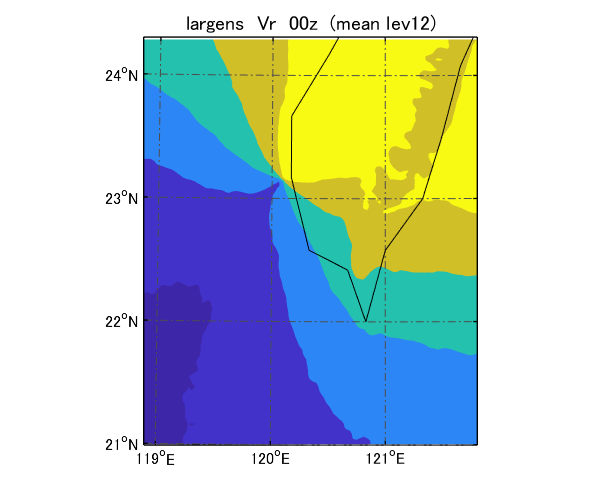

   %---plot---
   plotvar=vr;   %plotvar(plotvar<=0)=NaN;
   pmin=double(min(min(plotvar)));   if pmin<L(1); L2=[pmin,L]; else; L2=[L(1) L]; end
    %
   figure('position',[-800 500 600 500])
   m_proj('Lambert','lon',plon,'lat',plat,'clongitude',121,'parallels',[33.65 13.65],'rectbox','on')
   [c ,hp ]=m_contourf(x,y,plotvar);   set(hp,'linestyle','none');
   %
   %
   m_grid('fontsize',12,'LineStyle','-.','LineWidth',1,'xtick',115:130,'ytick',17:45);
   m_coast('color','k');
   %m_gshhs_h('color','k','LineWidth',0.8);
   %cm=colormap(cmap);
   %hc=Recolor_contourf(hp,cm,L,'vert');  set(hc,'fontsize',13,'LineWidth',1)
%---
   tit=[expri,'  ',varinam,'  ',s_hr,'z  (',type,' lev',num2str(lev),')'];
   outfile=[outdir,filenam,s_hr,'_',type,'_lev',num2str(lev)];
   title(tit,'fontsize',15)

   
   %print('-dpng',outfile,'-r400')
%    set(gcf,'PaperPositionMode','auto');  print('-dpdf',[outfile,'.pdf'])
%    system(['convert -trim -density 250 ',outfile,'.pdf ',outfile,'.png']);
%    system(['rm ',[outfile,'.pdf']]);


